%% Clean MILP + KPI + Economic BESS sizing

clearvars -except HalfHourly

%% Inputs
L  = HalfHourly.Load48(:);
PV = HalfHourly.PV48(:);

n  = 48;
dt = 0.5;

%% Fixed parameters
etaC = 0.95;
etaD = 0.95;

Pch_max  = 3;
Pdis_max = 3;

c_imp = 0.30 * ones(n,1);      % £/kWh

%% Economic parameters
capex_per_kWh  = 350;          % £/kWh BESS
battery_life   = 10;           % years

kWp = 3;                       % PV size
pv_capex_per_kWp = 1200;       % £/kWp
pv_life = 20;                  % years
pv_om_frac = 0.01;             % annual O&M fraction

pv_capex = kWp * pv_capex_per_kWp;
Cpv_day = pv_capex/(365*pv_life) + (pv_capex*pv_om_frac)/365;

%% Battery sweep settings
cap_values = (1:0.5:10)';
socMinFrac = 0.20;

daily_elec_cost = zeros(numel(cap_values),1);
daily_import    = zeros(numel(cap_values),1);
daily_total_cost = zeros(numel(cap_values),1);

opts = optimoptions('intlinprog','Display','none');

x_store = cell(numel(cap_values),1);

%% Capacity sweep
for kk = 1:numel(cap_values)

    SoC_max = cap_values(kk);
    SoC_min = socMinFrac * SoC_max;

    % Decision vector:
    % x = [p_imp; p_ch; p_dis; pv2L; pvcur; SoC(1:n+1); u_ch; u_dis]

    ix_imp   = 1:n;
    ix_ch    = n+(1:n);
    ix_dis   = 2*n+(1:n);
    ix_pv2L  = 3*n+(1:n);
    ix_pvcur = 4*n+(1:n);
    ix_soc   = 5*n+(1:n+1);
    ix_uch   = 6*n+1+(1:n);
    ix_udis  = 7*n+1+(1:n);

    Nx = 8*n + 1;

    %% Objective
    f = zeros(Nx,1);
    f(ix_imp) = c_imp * dt;

    epsR = 1e-6;
    f(ix_ch) = epsR;
    f(ix_dis) = epsR;

    curtail_pen = 1e-3;
    f(ix_pvcur) = curtail_pen * dt;

    %% Equalities

    % Load balance:
    % p_imp + p_dis + pv2L = L
    Aeq_load = sparse(n,Nx);
    Aeq_load(sub2ind([n Nx],(1:n)',ix_imp'))  = 1;
    Aeq_load(sub2ind([n Nx],(1:n)',ix_dis'))  = 1;
    Aeq_load(sub2ind([n Nx],(1:n)',ix_pv2L')) = 1;
    beq_load = L;

    % PV balance:
    % pv2L + p_ch + pvcur = PV
    Aeq_pv = sparse(n,Nx);
    Aeq_pv(sub2ind([n Nx],(1:n)',ix_pv2L'))  = 1;
    Aeq_pv(sub2ind([n Nx],(1:n)',ix_ch'))    = 1;
    Aeq_pv(sub2ind([n Nx],(1:n)',ix_pvcur')) = 1;
    beq_pv = PV;

    % SoC dynamics:
    % SoC(t+1) = SoC(t) + etaC*dt*p_ch - dt/etaD*p_dis
    Aeq_soc = sparse(n,Nx);
    Aeq_soc(sub2ind([n Nx],(1:n)',ix_soc(2:end)'))   = 1;
    Aeq_soc(sub2ind([n Nx],(1:n)',ix_soc(1:end-1)')) = -1;
    Aeq_soc(sub2ind([n Nx],(1:n)',ix_ch'))  = -etaC*dt;
    Aeq_soc(sub2ind([n Nx],(1:n)',ix_dis')) = +(1/etaD)*dt;
    beq_soc = zeros(n,1);

    % Cyclic SoC
    Aeq_cyc = sparse(1,Nx);
    Aeq_cyc(ix_soc(end)) = 1;
    Aeq_cyc(ix_soc(1))   = -1;
    beq_cyc = 0;

    Aeq = [Aeq_load; Aeq_pv; Aeq_soc; Aeq_cyc];
    beq = [beq_load; beq_pv; beq_soc; beq_cyc];

    %% Inequalities

    % p_ch <= Pch_max*u_ch
    Ach = sparse(n,Nx);
    Ach(sub2ind([n Nx],(1:n)',ix_ch'))  = 1;
    Ach(sub2ind([n Nx],(1:n)',ix_uch')) = -Pch_max;
    bh = zeros(n,1);

    % p_dis <= Pdis_max*u_dis
    Adis = sparse(n,Nx);
    Adis(sub2ind([n Nx],(1:n)',ix_dis'))  = 1;
    Adis(sub2ind([n Nx],(1:n)',ix_udis')) = -Pdis_max;
    bd = zeros(n,1);

    % u_ch + u_dis <= 1
    Amode = sparse(n,Nx);
    Amode(sub2ind([n Nx],(1:n)',ix_uch'))  = 1;
    Amode(sub2ind([n Nx],(1:n)',ix_udis')) = 1;
    bm = ones(n,1);

    % SoC-dependent discharge bound
    Adis_soc = sparse(n,Nx);
    Adis_soc(sub2ind([n Nx],(1:n)',ix_dis')) = 1;
    Adis_soc(sub2ind([n Nx],(1:n)',ix_soc(1:n)')) = -(etaD/dt);
    bdis_soc = -(etaD/dt)*SoC_min*ones(n,1);

    % SoC-dependent charge bound
    Ach_soc = sparse(n,Nx);
    Ach_soc(sub2ind([n Nx],(1:n)',ix_ch')) = 1;
    Ach_soc(sub2ind([n Nx],(1:n)',ix_soc(1:n)')) = 1/(etaC*dt);
    bch_soc = (SoC_max/(etaC*dt))*ones(n,1);

    A = [Ach; Adis; Amode; Ach_soc; Adis_soc];
    b = [bh; bd; bm; bch_soc; bdis_soc];

    %% Bounds
    lb = zeros(Nx,1);
    ub = inf(Nx,1);

    ub(ix_ch) = Pch_max;
    ub(ix_dis) = Pdis_max;

    lb(ix_soc) = SoC_min;
    ub(ix_soc) = SoC_max;

    ub(ix_uch) = 1;
    ub(ix_udis) = 1;

    intcon = [ix_uch ix_udis];

    %% Solve
    [x,fval,exitflag] = intlinprog(f,intcon,A,b,Aeq,beq,lb,ub,opts);

    if exitflag <= 0
        daily_elec_cost(kk) = NaN;
        daily_import(kk) = NaN;
        daily_total_cost(kk) = NaN;
        continue
    end

    p_imp = x(ix_imp);

    x_store{kk} = x;

    daily_elec_cost(kk) = sum(dt*c_imp.*p_imp);
    daily_import(kk) = dt * sum(p_imp);

    Cbess_day = cap_values(kk) * capex_per_kWh / (365*battery_life);

    daily_total_cost(kk) = daily_elec_cost(kk) + Cbess_day + Cpv_day;
end

%% Economic optimum
[best_total_cost, idx_best] = min(daily_total_cost,[],'omitnan');

best_cap = cap_values(idx_best);
best_import = daily_import(idx_best);
best_elec_cost = daily_elec_cost(idx_best);

%% Extract optimum solution
x_best = x_store{idx_best};

p_imp_best  = x_best(ix_imp);
p_ch_best   = x_best(ix_ch);
p_dis_best  = x_best(ix_dis);
pv2L_best   = x_best(ix_pv2L);
pvcur_best  = x_best(ix_pvcur);
SoC_best    = x_best(ix_soc);

%% Energy KPIs for economic optimum
E_load = dt * sum(L);
E_pv   = dt * sum(PV);
E_imp  = dt * sum(p_imp_best);
E_cur  = dt * sum(pvcur_best);
E_pv2B = dt * sum(p_ch_best);
E_pv2L = dt * sum(pv2L_best);
E_dis  = dt * sum(p_dis_best);

%% Baseline without HEMS
p_imp_base = max(L - PV, 0);
Cost_noHEMS_day = sum(dt*c_imp.*p_imp_base);
Cost_noHEMS_year = 365 * Cost_noHEMS_day;

Cost_withHEMS_year = 365 * best_total_cost;
Saving_year = Cost_noHEMS_year - Cost_withHEMS_year;
Reduction_pct = 100 * Saving_year / Cost_noHEMS_year;

%% KPI output
fprintf('\n===== Economic BESS Analysis =====\n');


===== Economic BESS Analysis =====


fprintf('Baseline without HEMS: £%.2f/year\n', Cost_noHEMS_year);

Baseline without HEMS: £626.31/year


fprintf('Economic optimum BESS size: %.1f kWh\n', best_cap);

Economic optimum BESS size: 7.5 kWh


fprintf('Daily electricity cost at optimum: £%.2f/day\n', best_elec_cost);

Daily electricity cost at optimum: £0.01/day


fprintf('Daily total cost at optimum: £%.2f/day\n', best_total_cost);

Daily total cost at optimum: £1.32/day


fprintf('Yearly total cost with HEMS: £%.2f/year\n', Cost_withHEMS_year);

Yearly total cost with HEMS: £480.66/year


fprintf('Yearly saving: £%.2f/year\n', Saving_year);

Yearly saving: £145.65/year


fprintf('Yearly reduction: %.2f %%\n', Reduction_pct);

Yearly reduction: 23.26 %



fprintf('\n===== Optimum Case Energy KPIs =====\n');


===== Optimum Case Energy KPIs =====


fprintf('Total household load     : %.2f kWh/day\n', E_load);

Total household load     : 12.66 kWh/day


fprintf('Total PV generation      : %.2f kWh/day\n', E_pv);

Total PV generation      : 13.71 kWh/day


fprintf('Grid import              : %.2f kWh/day\n', E_imp);

Grid import              : 0.02 kWh/day


fprintf('PV to battery            : %.2f kWh/day\n', E_pv2B);

PV to battery            : 6.67 kWh/day


fprintf('PV to load               : %.2f kWh/day\n', E_pv2L);

PV to load               : 6.62 kWh/day


fprintf('PV curtailed             : %.2f kWh/day\n', E_cur);

PV curtailed             : 0.43 kWh/day


fprintf('Battery discharge        : %.2f kWh/day\n', E_dis);

Battery discharge        : 6.02 kWh/day


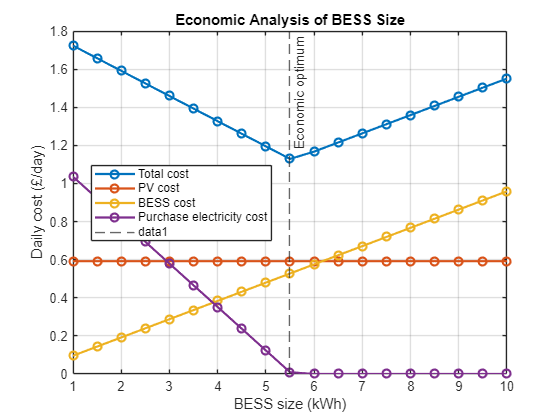


%% Plot economic analysis
Cbess_day_vec = cap_values * capex_per_kWh / (365*battery_life);
Cpv_day_vec = Cpv_day * ones(size(cap_values));

figure('Color','w'); hold on
plot(cap_values,daily_total_cost,'-o','LineWidth',1.6);
plot(cap_values,Cpv_day_vec,'-o','LineWidth',1.6);
plot(cap_values,Cbess_day_vec,'-o','LineWidth',1.6);
plot(cap_values,daily_elec_cost,'-o','LineWidth',1.6);

grid on; box on
xlabel('BESS size (kWh)');
ylabel('Daily cost (£/day)');
title('Economic Analysis of BESS Size');
legend({'Total cost','PV cost','BESS cost','Purchase electricity cost'}, ...
       'Location','best');

xline(best_cap,'--','Economic optimum');

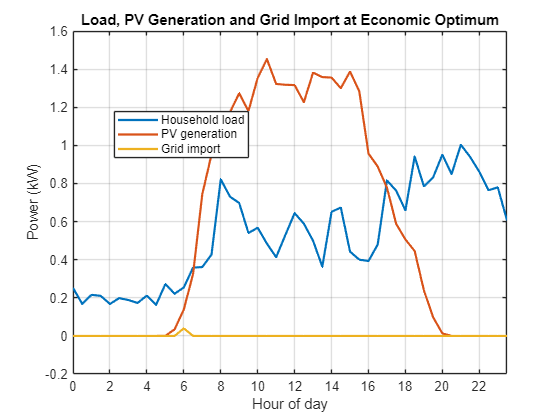


%% Plot load, PV generation and grid import for optimum case

t = (0:n-1)' * dt;

figure('Color','w');
plot(t, L, 'LineWidth', 1.6); hold on
plot(t, PV, 'LineWidth', 1.6);
plot(t, p_imp_best, 'LineWidth', 1.6);

grid on; box on
xlabel('Hour of day');
ylabel('Power (kW)');
title('Load, PV Generation and Grid Import at Economic Optimum');
legend({'Household load','PV generation','Grid import'}, ...
       'Location','best');

xlim([0 23.5]);
xticks(0:2:24);


%% Results table
Results = table(cap_values, daily_import, daily_elec_cost, ...
    Cbess_day_vec, Cpv_day_vec, daily_total_cost, ...
    'VariableNames', {'BESS_kWh','Import_kWh_day','ElectricityCost_day', ...
    'BESSCost_day','PVCost_day','TotalCost_day'});

disp(Results);

    BESS_kWh    Import_kWh_day    ElectricityCost_day    BESSCost_day    PVCost_day    TotalCost_day
    ________    ______________    ___________________    ____________    __________    _____________

        1             4.9598              1.4879           0.09589        0.59178         2.1756    
      1.5             4.5798              1.3739           0.14384        0.59178         2.1095    
        2             4.1998              1.2599           0.19178        0.59178         2.0435    
      2.5             3.8198              1.1459           0.23973        0.59178         1.9774    
        3             3.4398              1.0319           0.28767        0.59178         1.9114    
      3.5             3.0598             0.91793           0.33562        0.59178       